#  MHKit Short-term Extreme Loads Example

S`hort-term extreme loads are typically required as part of a long-term extreme load estimate. `

`A short-term extreme distribution is a probability distribution for the extreme value of a short-term (e.g. 3-hours) time-series. `

`MHKiT includes functions adapted from the `[`WDRT`](https://github.com/WEC-Sim/WDRT)` for estimating the short-term extreme distribution. `

`Several methods are included, which can be divided into two main  approaches:`

- `Block maxima: approximate the short-term extreme distribution directly by fitting a probability distribution to the maxima from N distinct short-term blocks. `

- `Peaks distribution: approximate the short-term extreme distribution from the distribution of peaks from a time-series of arbitrary length. `

`The two sets of methods will be demonstrated. `

`**NOTE**``: This notebook will walk through the two different approaches, and each method in them. The short-term extremes will be obtained step-by-step showing the intermediate outputs. However, a convenience function, the `[`loads.extreme.short_term_extreme`](..\mhkit\loads\extreme\short_term_extreme.m)` function, can be be used directly in a single step. For this usage jump to the last section. It is recommended that you go over this entire example to understand what is going on "under the hood" prior to using this convenience function. `

`The quantity (load) of interest can be anything related to the WEC, such as position (e.g. PTO extension, heave displacement), velocity, structural load, mooring loads, etc. For this example we will use the wave elevation as the quantity of interest, since such time-series can be easily created without having to run a WEC-modeling software. The short-term period of interest will be 3-hours.`

`An important pre-processing step is making the time-series zero-mean. In this case, since wave elevation is zero-mean no pre-processing is needed. `

`We  will start by creating the response time-series using the ``loads.extreme`` module which includes these different methods, and the ``wave.resource`` module.`

`We first define the short-term period (3 hours).`

% Short-term period in seconds
t_st = 3.0 * 60.0 * 60.0;

`The methods based on peaks distributions require a single time series of any length while the methods based on block maxima require N time series of length equal to the short-term time period. `

`We will now create N=10 time series of length equal to the short-term period (3 hours). For block maxima methods we will use all 10 and for peaks distribution methods we will only use the first hour of the first time-series. For the block maxima we use N=10 for speed considerations, but note that this would be inadequately small for most real applications. `

`For the sake of example we will consider the wave elevation as the quantity of interest (can be thought as a proxy for heave motion in this example). Wave elevation time-series for a specific sea state can be created quickly without running any external software. `

`**NOTE:**`` The code below is simply creating the synthetic data (wave elevation time series). In a realistic case the time series would be obtained externally, e.g. through simulation software such as WEC-Sim or CFD. For this reason the details of creating the synthetic data are not presented here, instead assume for the quantity of interest there are ten 3-hours time-series available. `

`We start by creating the ten 3-hour time-series of  the  quantity of interest. We do this with a list comprehension and using the `[`wave.resource.surface_elevation`](..\mhkit\wave\resource\surface_elevation.m)` function. The result is a list of 10 different time-series. Alternatively we could have created a single time-series of length N times the short-term period (30 hours) and used the `[`extreme.block_maxima`](..\mhkit\loads\extreme\block_maxima.m)` function to split it into blocks and return the block maxima. `

% JSONWAP spectrum for creating short-term time-serires
T_min = 1;  % second
Tp = 8;     % second
Hs = 1.5;   % meters
f0 = 1/t_st;
f_max = 1/T_min;
Nf = int32(f_max/f0);
f = linspace(f0, f_max, Nf);
S = jonswap_spectrum(f, Tp, Hs);

% time in seconds
time = linspace(0, t_st, 2*Nf + 1);

% 10 distinct time-series
N = 10;
qoi_timeseries = cell([1,N]);
for qq = 1:N
    qoi_timeseries{qq}= surface_elevation(S, time, "seed", qq);
end

`We can view the different time-series. Change value of ``i`` below to plot a different time-series. Below we plot both the full 3 hours time series and the first 2 minutes to get a better look at the behavior of the response.`

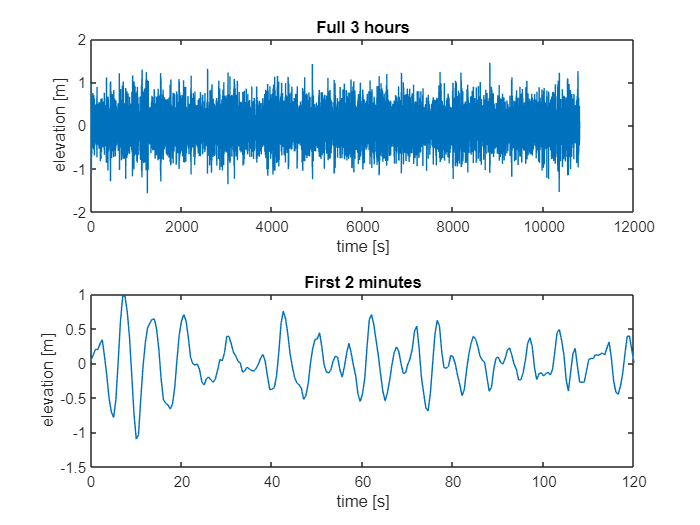

i = 1;   % 1 - 10
timeseries = qoi_timeseries{i};

tiledlayout(2,1)
ax1 = nexttile;
plot(ax1,time,timeseries.elevation);
title(ax1,'Full 3 hours')
xlabel(ax1,'time [s]')
ylabel(ax1,'elevation [m]')

mask = time <= 120;
ax2 = nexttile;
plot(ax2,time(mask),timeseries.elevation(mask));
title(ax2,'First 2 minutes')
xlabel(ax2,'time [s]')
ylabel(ax2,'elevation [m]')

## Block Maxima

`The short-term extreme distribution can be estimated directly from N time-series of short-term period. `

`These time-series can be obtained, for instance, from N distinct simulations of the quantity of interest, or alternatively by dividing a long time-series of the quantity of interest  into blocks of length equal to the short-term period. In this example we will use N=10 for speed considerations, but this would be inadequately small for most real applications. `

### `1. Find the maximum of each block`

`The first step is to get the maximum in each block, i.e. in each of the ten time series. We do this with a list comprehension. The result is a list of the 10 block maxima.`

block_maxima = zeros(size(qoi_timeseries));
for qq = 1:N
    block_maxima(qq) = max(qoi_timeseries{qq}.elevation);
end
block_maxima

block_maxima =     1.4531    1.3615    1.4971    1.4557    1.4316    1.4560    1.5771    1.6664    1.4218    1.4168


`We can view the different time-series and their maxima. Change value of i below to plot a different time-series. `

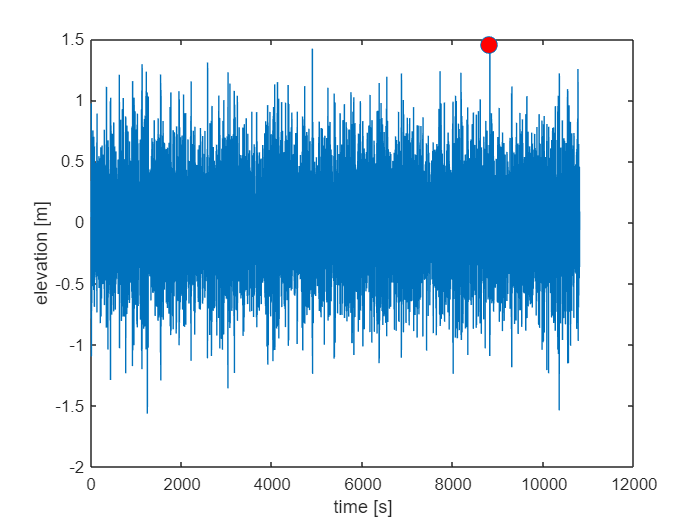

i = 1; % select: 1-10

idxmax = find(qoi_timeseries{i}.elevation == block_maxima(i));

figure
plot(time,qoi_timeseries{i}.elevation,'-o','MarkerIndices',[idxmax],...
    'MarkerFaceColor','red','MarkerSize',10)
xlabel('time [s]')
ylabel('elevation [m]')